load ADC_FResp_Data.mat;

% Calculate amplitude:
% I know this is not the most scientific way...
ampl = zeros(n_steps);
for i = 1:n_steps
    ampl(i) = max(data(i,:))-min(data(i,:));
end

% Calculate relative amplitude:
ampl = ampl/max(ampl);

% Convert to db:
ampl = 20*log10(ampl);

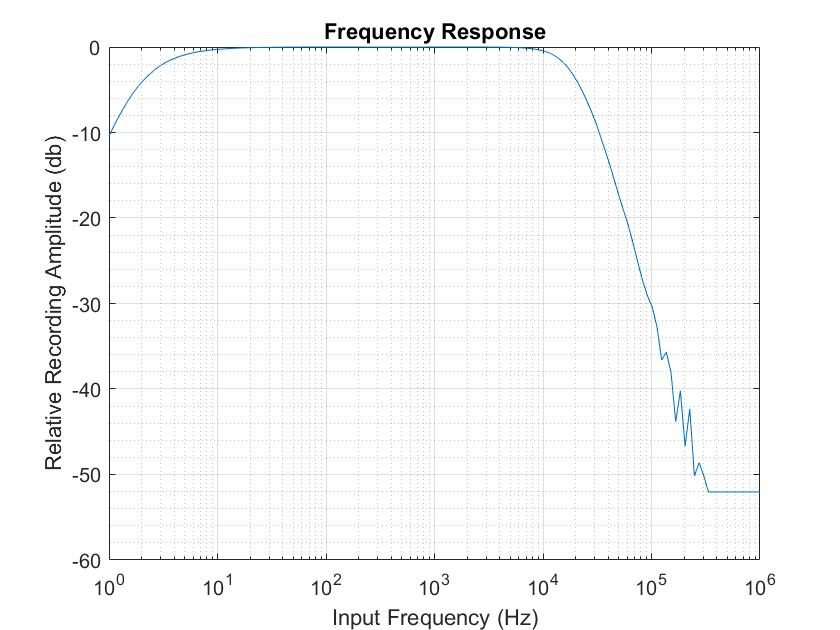

% Plot
figure();
semilogx(set_point, ampl);
title('Frequency Response')
grid ON;
grid MINOR;
xlabel('Input Frequency (Hz)');
ylabel('Relative Recording Amplitude (db)');